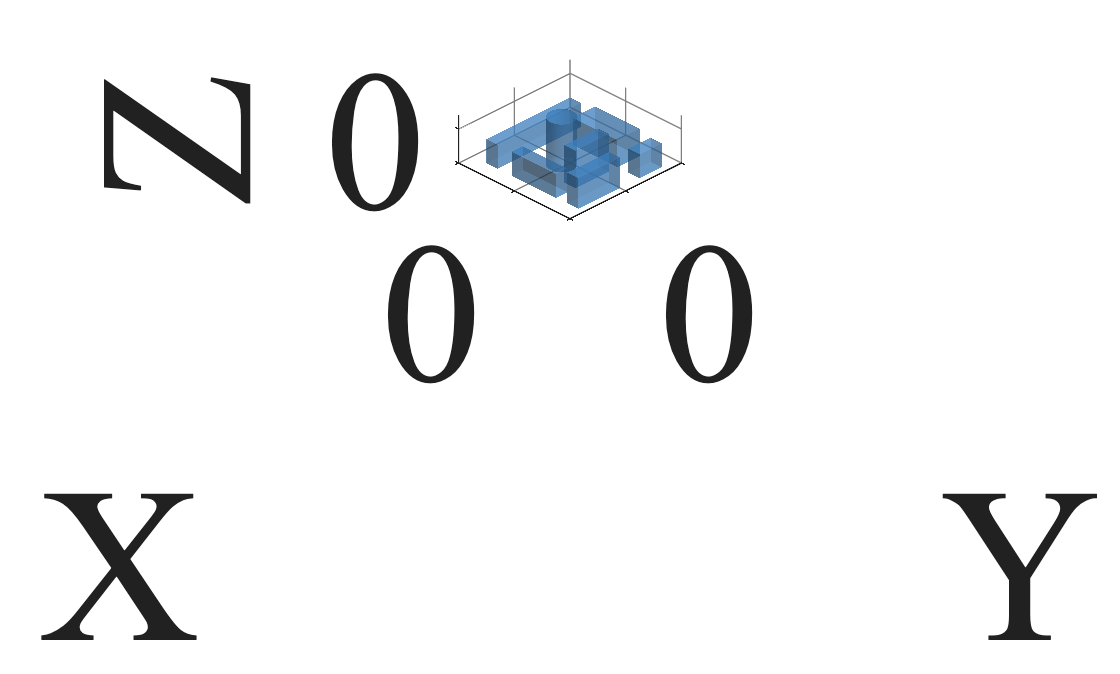

%% 저장 폴더 확인
if ~exist('./matlab/results','dir'); mkdir('./matlab/results'); end

%% STL 파일 목록 (7개 파일 포함)
file_names = {'mesh0.stl', 'mesh1.stl', 'mesh2.stl', 'mesh3.stl', 'mesh4.stl', 'mesh5.stl', 'mesh6.stl'};

%% 모든 STL 파일을 개별 메쉬로 결합
combined_mesh = combine_stls(file_names);

%% 공통 스타일
object_alpha = 0.5;                 % 알파값 (0: 완전 투명, 1: 불투명)
material_params = [0.3 0.6 0.1 20 1];

fs_title = 70; fs_label = 75; fs_tick = 75;

% (원래 전체 figure 9x4의 반쪽 subplot 크기 정도로 맞춤)
fig_w = 4.0;     % inches
fig_h = 4.0;     % inches

%% =========================
% 1) (a) 3D View: 별도 저장
%% =========================
fig3d = figure('Color','w', 'InvertHardcopy','off');
set(fig3d, 'PaperUnits','inches', 'PaperPosition',[0 0 fig_w fig_h]);

ax3d = axes(fig3d); %#ok<LAXES>
hold(ax3d, 'on');

object_color_3d = [0.3216 0.6667 1];
for i = 1:length(file_names)
    patch(ax3d, 'Faces', combined_mesh.faces{i}, ...
               'Vertices', combined_mesh.vertices{i}, ...
               'FaceColor', object_color_3d, ...
               'FaceAlpha', object_alpha, ...
               'EdgeColor', 'none', ...
               'FaceLighting', 'flat');
end
hold(ax3d, 'off');

axis(ax3d, 'equal');
xlim(ax3d, [-100, 100]); ylim(ax3d, [-100, 100]);
xlabel(ax3d, 'X', 'FontName', 'Times New Roman', 'FontSize', fs_label);
ylabel(ax3d, 'Y', 'FontName', 'Times New Roman', 'FontSize', fs_label);
zlabel(ax3d, 'Z', 'FontName', 'Times New Roman', 'FontSize', fs_label);
% title(ax3d, '(a) 3D View', 'FontName', 'Times New Roman', 'FontSize', fs_title);

set(ax3d, 'FontSize', fs_tick, 'FontName', 'Times New Roman', 'Color', 'none');
grid(ax3d, 'on');
set(ax3d, 'GridAlpha', 1, 'GridColor', [0.5 0.5 0.5]);

view(ax3d, 45, 30);
axes(ax3d); %#ok<LAXES>
material(material_params);
camlight(ax3d, 'infinite');

% 저장 (각각 따로)
print(fig3d, './matlab/results/env_setup_3d', '-dpng', '-r600');
print(fig3d, './matlab/results/env_setup_3d', '-dpdf', '-r600');

% EPS: 조명 유지 + 고해상도 래스터 EPS (OpenGL)
set(fig3d, 'Renderer', 'opengl');
print(fig3d, './matlab/results/env_setup_3d', '-depsc', '-opengl', '-r600');

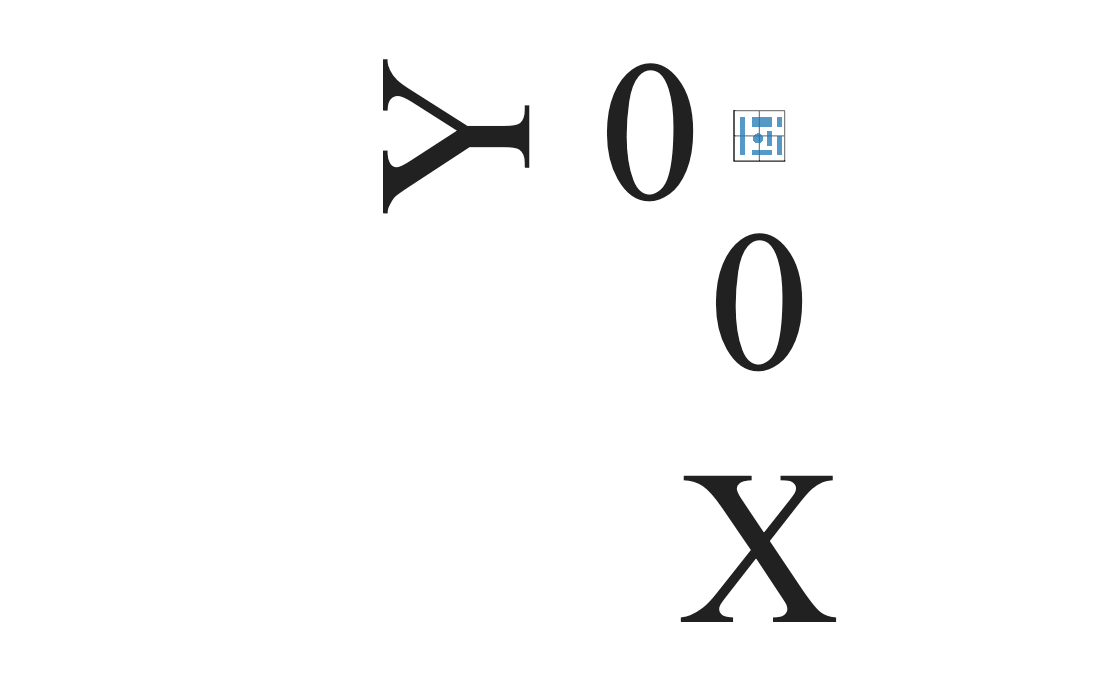


%% =========================
% 2) (b) XY-Plane View: 별도 저장
%% =========================
figxy = figure('Color','w', 'InvertHardcopy','off');
set(figxy, 'PaperUnits','inches', 'PaperPosition',[0 0 fig_w fig_h]);

axxy = axes(figxy); %#ok<LAXES>
hold(axxy, 'on');

object_color_xy = [0.1216 0.4667 0.7059];
for i = 1:length(file_names)
    patch(axxy, 'Faces', combined_mesh.faces{i}, ...
               'Vertices', combined_mesh.vertices{i}, ...
               'FaceColor', object_color_xy, ...
               'FaceAlpha', object_alpha, ...
               'EdgeColor', 'none');
end
hold(axxy, 'off');

view(axxy, 0, 90);
axis(axxy, 'equal');
xlim(axxy, [-100, 100]); ylim(axxy, [-100, 100]);
xlabel(axxy, 'X', 'FontName', 'Times New Roman', 'FontSize', fs_label);
ylabel(axxy, 'Y', 'FontName', 'Times New Roman', 'FontSize', fs_label);
% title(axxy, '(b) XY-Plane View', 'FontName', 'Times New Roman', 'FontSize', fs_title);

set(axxy, 'FontSize', fs_tick, 'FontName', 'Times New Roman', 'Color', 'none');
grid(axxy, 'on');
set(axxy, 'GridAlpha', 1, 'GridColor', [0.5 0.5 0.5]);

% 저장 (각각 따로)
print(figxy, './matlab/results/env_setup_xy', '-dpng', '-r600');
print(figxy, './matlab/results/env_setup_xy', '-dpdf', '-r600');

% EPS: OpenGL 래스터 EPS
set(figxy, 'Renderer', 'opengl');
print(figxy, './matlab/results/env_setup_xy', '-depsc', '-opengl', '-r600');


%% ========== Local function (script 끝에 위치 권장) ==========
function combined_mesh = combine_stls(file_names)
    combined_mesh.vertices = cell(1, length(file_names));
    combined_mesh.faces    = cell(1, length(file_names));

    for i = 1:length(file_names)
        TR = stlread(file_names{i});           % triangulation
        combined_mesh.vertices{i} = TR.Points;
        combined_mesh.faces{i}    = TR.ConnectivityList;
    end
end
